## Ref IL computation using Standard IL method and threshold computation for single-truck events

The purpose of this code is to compute the reference ILs using standard IL method and threshold computation for single-truck events. A detailed explanation is provided in my dissertation (chapter 4) to show how to calculate the RefILs and thresholds. This instruction is only to accelerate the implementation of the code by future readers. 

In this code, two functions are needed, one for A_MATRIX and one for B_MATRIX. Please see chapter 2 in my disertation for their definitions. Make sure that these two functions are beside the main code. In all codes A_MATRIX and B_MATRIX are not needed to be changed and they are the same for all codes.

In this code, TP stands for transverse position. TP1= transverse position 1 (when centerline offset in the CSI Bridge for lane 2 is set to be +0.1), TP2= transverse position 2 (when there is no transverse position change for Lane 2 that is when centerline offset in the CSI Bridge for lane 2 is set to be -0.2), and TP3= transverse position 3 (when centerline offset in the CSI Bridge for lane 2 is set to be -0.5). (This is explained in the CSI Bridge Instruction how to change the transverse position.)

Here is an instruction about the following tests:

Tests 1 through 9 are used to compute the Ref ILs using standard IL for 3-axle (using tests 1,2,3), 4-axle (using tests 4,5,6), and 5-axle trucks (using tests 7,8,9).

Test 1: single-3-axle truck on the intact bridge in transverse position 1

Test 2: single-3-axle truck on the intact bridge in transverse position 2

Test 3: single-3-axle truck on the intact bridge in transverse position 3

And IL17 is going to be the RefIL for the 3-axle truck considering truck passages in Tests 1,2,3. Future 3-axle truck passages should be compared with IL17 to determine if any damage has happened. 

Test 4: single-4-axle truck on the intact bridge in transverse position 1

Test 5: single-4-axle truck on the intact bridge in transverse position 2

Test 6: single-4-axle truck on the intact bridge in transverse position 3

And IL18 is going to be the RefIL for the 4-axle truck considering truck passages in Tests 4,5,6. Future 4-axle truck passages should be compared with IL18 to determine if any damage has happened. 

Test 7: single-5-axle truck on the intact bridge in transverse position 1

Test 8: single-5-axle truck on the intact bridge in transverse position 2

Test 9: single-5-axle truck on the intact bridge in transverse position 3

And IL19 is going to be the RefIL for the 5-axle truck considering truck passages in Tests 7,8,9. Future 5-axle truck passages should be compared with IL19 to determine if any damage has happened. 

**I have commented and explained the first test (Test 1) as follows and other tests can be described in a similar way.**


clear;
close;
clc;



## Test 1 (3-axle_LANE2)

Here we first load the data for the single 3-axle on lane 2 and on the intact bridge and on TP1. 

'6035_Intact_Single3axle_TP1 means the strain is extracted from node 6035 in CSI bridge software. Node 6035 is approximately where max local strain happens. It also shows it is extracted from a single truck event and on intact bridge and TP1.

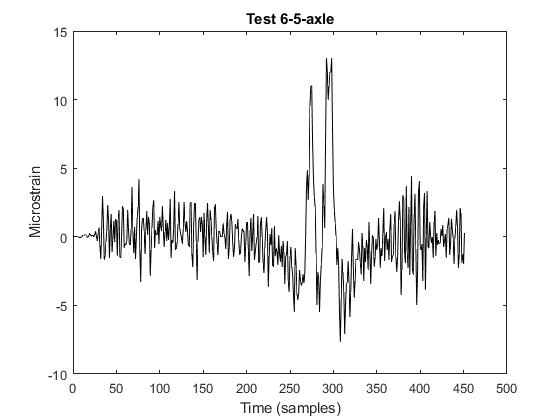

Data1 = textread('6035_Intact_Single3axle_TP1.txt');



plot(Data1,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

% 
Test1_st40=Data1;

Test1_st40=Test1_st40';


Here I am isolating the peaks manually to later use only movemean function on other parts of response. The purpose is to keep the peaks as it is (since they are not usually noisy) and to only make other parts smooth. Another way is to use other denoising tecniques such as wavelet etc. 

T1=Test1_st40(1:271);
T2=Test1_st40(272:279);
T3=Test1_st40(280:286);
T4=Test1_st40(287:303);
T5=Test1_st40(304:end-33);


T1 = movmean(T1,[10 0]);
T3 = movmean(T3,[10 0]);
T5 = movmean(T5,[10 0]);


Test1_st40=[T1 T2 T3 T4 T5];

Test1_st40=Test1_st40';


Let's plot the denoised response

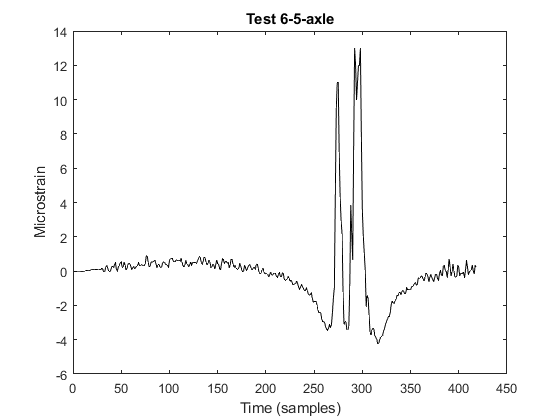

figure
plot(Test1_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

So far, we removed the noise from damping ratio of zero directly caused in the CSI Bridge. Now, we add noise content and we denoise it again in a similar way.

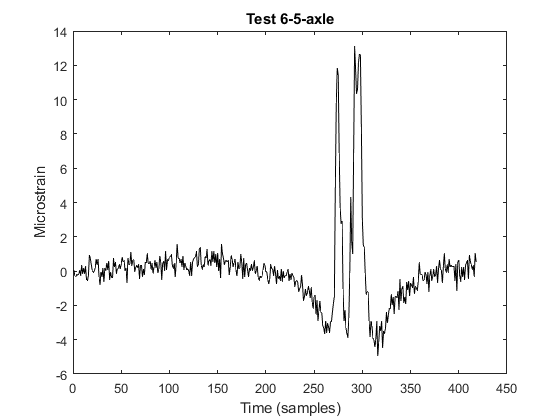

Test1_st40=Test1_st40+0.4*randn(length(Test1_st40),1);
plot(Test1_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

Test1_st40=Test1_st40';

T1=Test1_st40(150:271);
T2=Test1_st40(272:279);
T3=Test1_st40(280:286);
T4=Test1_st40(287:303);
T5=Test1_st40(304:end);


T1 = movmean(T1,[10 0]);

T2=movmean(T2,[2 0]);

T3 = movmean(T3,[10 0]);

T4=movmean(T4,[2 0]);

T5 = movmean(T5,[10 0]);


Test1_st40=[T1 T2 T3 T4 T5];

Test1_st40=Test1_st40';


Let's plot the denoised response

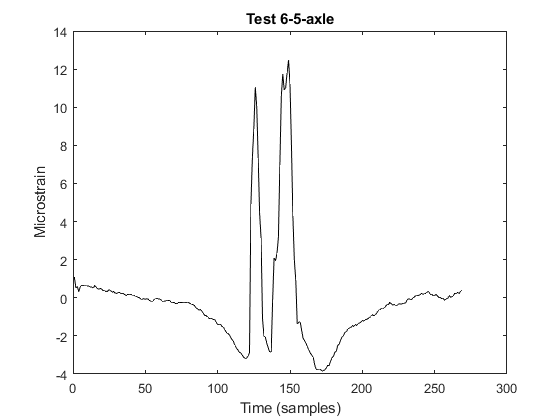

plot(Test1_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

## Inputs

Here we get the truck information. Please see the first paper (experimental case study) or my PhD dissertation (chapter 2) for details and to know what these parameters are. I have also commented them below for clarification

N_T1=3;          %% the number of axles
v1_T1=25;        %% speed m/s
f_T1=100;        %% sampling rate (Hz)
d1_T1=0;         %% the distance of the first axle from the first axle (m) --> This is always zero
d2_T1=4.5;       %% the distance of the second axle from the first axle (m) 
d3_T1=1.31;      %% the distance of the third axle from the first axle (m) 


% Axle weights

Weights_T1=[9.1 7.1 7.1];

% D vector using the d values already defined 

D1_vec_T1=[d1_T1 d1_T1+d2_T1 d1_T1+d2_T1+d3_T1];

% Calculating c values based on speed, sampling rate, and d values

c1_T1=D1_vec_T1(1)*f_T1/v1_T1;
c2_T1=D1_vec_T1(2)*f_T1/v1_T1;
c3_T1=D1_vec_T1(3)*f_T1/v1_T1;


C1_vec_T1=round([c1_T1 c2_T1 c3_T1]);

[row1_T1 col1_T1]=size(Test1_st40);
k1_T1=row1_T1;                      %% Total number of scans


This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data) and returns the Matrix A. This matrix is later used for IL computation.


[A_mat_T1]=A_MATRIX(N_T1,k1_T1,C1_vec_T1,Weights_T1);

## Test 2 (3-axle_LANE2)

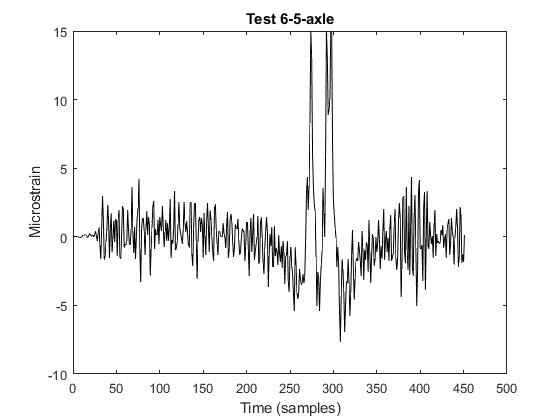

Data2 = textread('6035_Intact_Single3axle_TP2.txt');



plot(Data2,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

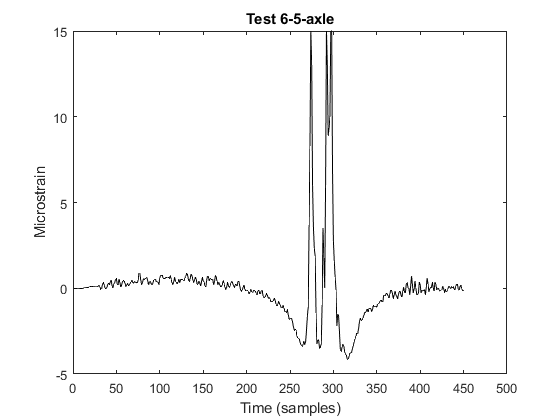

% 
Test2_st40=Data2;
Test2_st40=Test2_st40';


T1=Test2_st40(1:271);
T2=Test2_st40(272:279);
T3=Test2_st40(280:286);
T4=Test2_st40(287:303);
T5=Test2_st40(304:end);





T1 = movmean(T1,[10 0]);
T3 = movmean(T3,[10 0]);
T5 = movmean(T5,[10 0]);

Test2_st40=[T1 T2 T3 T4 T5];


Test2_st40=Test2_st40';


figure
plot(Test2_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')


% Test2_st40=Test2_st40+0.4*randn(length(Test2_st40),1);
plot(Test2_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

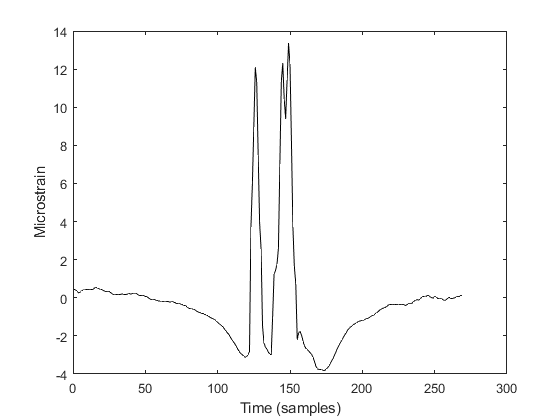

Test2_st40=Test2_st40';


T1=Test2_st40(150:271);
T2=Test2_st40(272:279);
T3=Test2_st40(280:286);
T4=Test2_st40(287:303);
T5=Test2_st40(304:end-33);



T1 = movmean(T1,[10 0]);

T2=movmean(T2,[2 0]);

T3 = movmean(T3,[10 0]);

T4=movmean(T4,[2 0]);

T5 = movmean(T5,[10 0]);


Test2_st40=[T1 T2 T3 T4 T5];

Test2_st40=Test2_st40';

plot(Test2_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

## Inputs

N_T2=3;          %% the number of axles
v1_T2=25;     %% m/s
f_T2=100;        %% Hz
d1_T2=0;         %% m
d2_T2=4.5;      %% m
d3_T2=1.31;      %% m
Weights_T2=[9.1 7.1 7.1];


D1_vec_T2=[d1_T2 d1_T2+d2_T2 d1_T2+d2_T2+d3_T2];

c1_T2=D1_vec_T2(1)*f_T2/v1_T2;
c2_T2=D1_vec_T2(2)*f_T2/v1_T2;
c3_T2=D1_vec_T2(3)*f_T2/v1_T2;


C1_vec_T2=round([c1_T2 c2_T2 c3_T2]);

[row1_T2 col1_T2]=size(Test2_st40);
k1_T2=row1_T2;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T2]=A_MATRIX(N_T2,k1_T2,C1_vec_T2,Weights_T2);

## Test 3 (3-axle_LANE2)

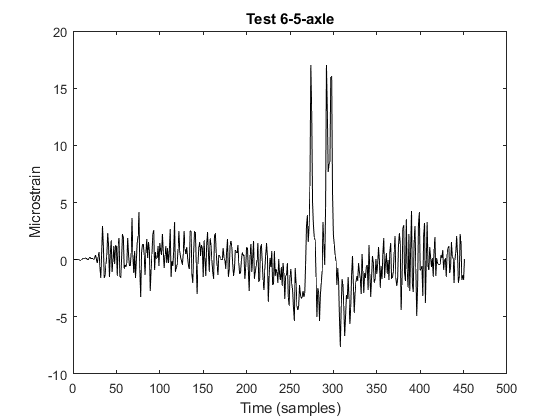

Data3 = textread('6035_Intact_Single3axle_TP3.txt');
plot(Data3,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

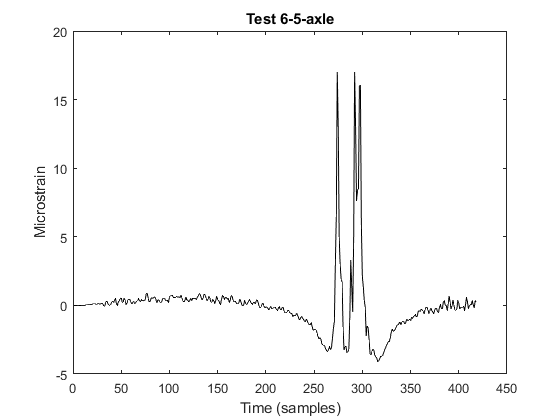

% 
Test3_st40=Data3;
Test3_st40=Test3_st40';

T1=Test3_st40(1:271);
T2=Test3_st40(272:279);
T3=Test3_st40(280:286);
T4=Test3_st40(287:303);
T5=Test3_st40(304:end-33);


T1 = movmean(T1,[10 0]);
T3 = movmean(T3,[10 0]);
T5 = movmean(T5,[10 0]);


Test3_st40=[T1 T2 T3 T4 T5];

Test3_st40=Test3_st40';

figure
plot(Test3_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

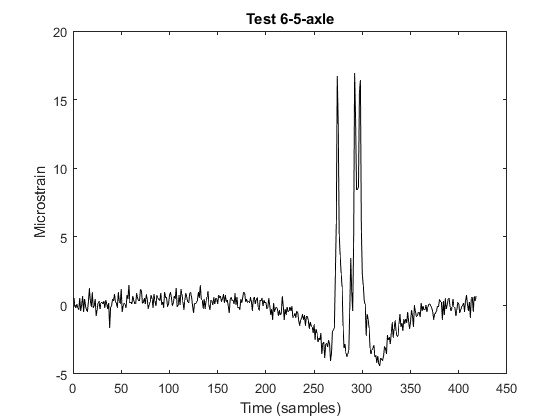

Test3_st40=Test3_st40+0.4*randn(length(Test3_st40),1);
plot(Test3_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

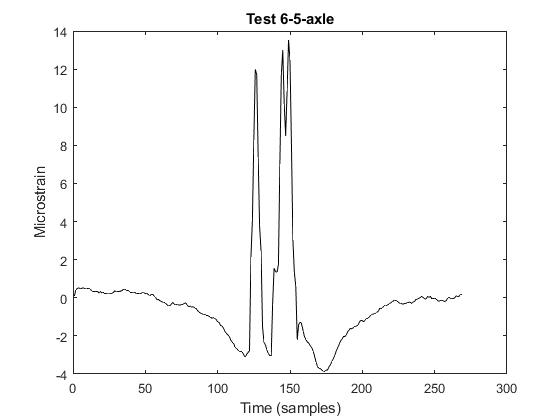



Test3_st40=Test3_st40';

T1=Test3_st40(150:271);
T2=Test3_st40(272:279);
T3=Test3_st40(280:286);
T4=Test3_st40(287:303);
T5=Test3_st40(304:end);

T1 = movmean(T1,[10 0]);

T2=movmean(T2,[2 0]);

T3 = movmean(T3,[10 0]);

T4=movmean(T4,[2 0]);

T5 = movmean(T5,[10 0]);


Test3_st40=[T1 T2 T3 T4 T5];

Test3_st40=Test3_st40';

plot(Test3_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

## Inputs

N_T3=3;          %% the number of axles
v1_T3=25;     %% m/s
f_T3=100;        %% Hz
d1_T3=0;         %% m
d2_T3=4.5;      %% m
d3_T3=1.31;      %% m



Weights_T3=[9.1 7.1 7.1];

D1_vec_T3=[d1_T3 d1_T3+d2_T3 d1_T3+d2_T3+d3_T3];

c1_T3=D1_vec_T3(1)*f_T3/v1_T3;
c2_T3=D1_vec_T3(2)*f_T3/v1_T3;
c3_T3=D1_vec_T3(3)*f_T3/v1_T3;


C1_vec_T3=round([c1_T3 c2_T3 c3_T3]);

[row1_T3 col1_T3]=size(Test3_st40);
k1_T3=row1_T3;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T3]=A_MATRIX(N_T3,k1_T3,C1_vec_T3,Weights_T3);

## Test 4 (4-axle_LANE2)

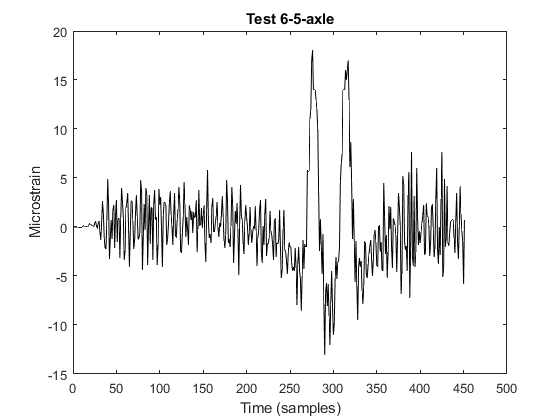

Data4 = textread('6035_Intact_Single4axle_TP1.txt');
plot(Data4,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

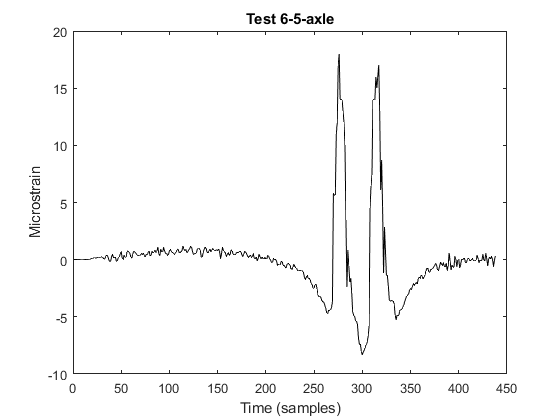

% 
Test4_st40=Data4;
Test4_st40=Test4_st40';

T1=Test4_st40(1:269);
T2=Test4_st40(270:284);
T3=Test4_st40(285:307);
T4=Test4_st40(308:322);
T5=Test4_st40(323:end-13);


T1 = movmean(T1,[10 0]);
T3 = movmean(T3,[10 0]);
T5 = movmean(T5,[10 0]);

Test4_st40=[T1 T2 T3 T4 T5];
Test4_st40=Test4_st40';

figure
plot(Test4_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

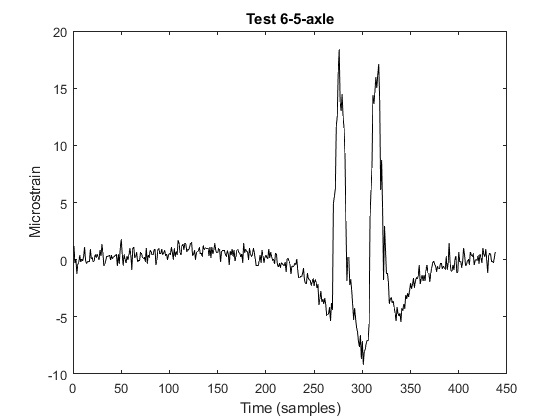

Test4_st40=Test4_st40+0.4*randn(length(Test4_st40),1);
plot(Test4_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

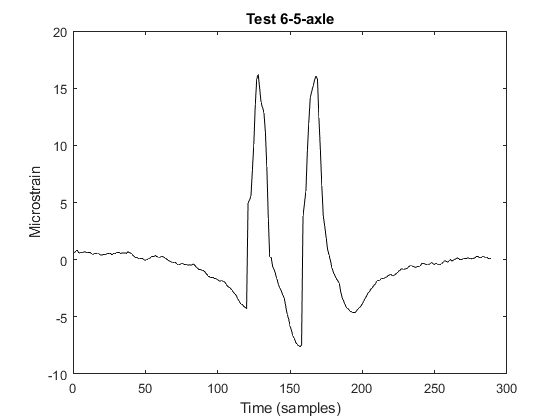



Test4_st40=Test4_st40';

T1=Test4_st40(150:269);
T2=Test4_st40(270:284);
T3=Test4_st40(285:307);
T4=Test4_st40(308:322);
T5=Test4_st40(323:end);


T1 = movmean(T1,[10 0]);

T2=movmean(T2,[2 0]);

T3 = movmean(T3,[10 0]);

T4=movmean(T4,[2 0]);

T5 = movmean(T5,[10 0]);


Test4_st40=[T1 T2 T3 T4 T5];

Test4_st40=Test4_st40';

plot(Test4_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

## Inputs

N_T4=4;          %% the number of axles
v1_T4=25;     %% m/s
f_T4=100;        %% Hz
d1_T4=0;         %% m
d2_T4=1.4;      %% m
d3_T4=8;      %% m
d4_T4=1.4;     %% m



Weights_T4=[9 9 9 9];

D1_vec_T4=[d1_T4 d1_T4+d2_T4 d1_T4+d2_T4+d3_T4 d1_T4+d2_T4+d3_T4+d4_T4];

c1_T4=D1_vec_T4(1)*f_T4/v1_T4;
c2_T4=D1_vec_T4(2)*f_T4/v1_T4;
c3_T4=D1_vec_T4(3)*f_T4/v1_T4;
c4_T4=D1_vec_T4(4)*f_T4/v1_T4;


C1_vec_T4=round([c1_T4 c2_T4 c3_T4 c4_T4]);

[row1_T4 col1_T4]=size(Test4_st40);
k1_T4=row1_T4;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T4]=A_MATRIX(N_T4,k1_T4,C1_vec_T4,Weights_T4);


## Test 5 (4-axle_LANE2)

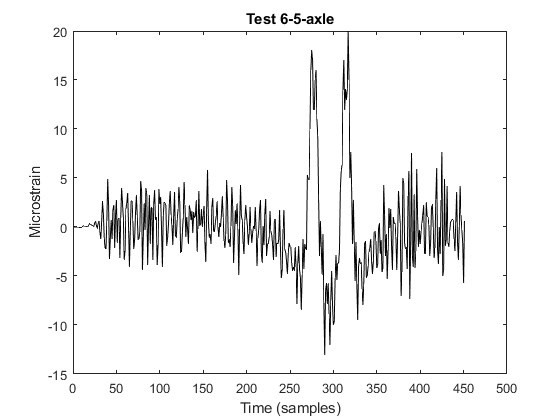

Data5 = textread('6035_Intact_Single4axle_TP2.txt');
plot(Data5,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

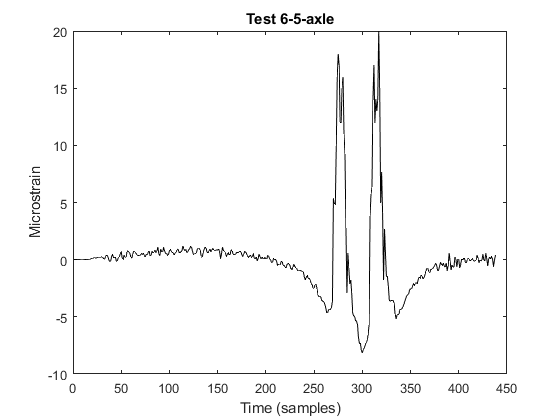

% 
Test5_st40=Data5;
Test5_st40=Test5_st40';

T1=Test5_st40(1:269);
T2=Test5_st40(270:284);
T3=Test5_st40(285:307);
T4=Test5_st40(308:322);
T5=Test5_st40(323:end-13);


T1 = movmean(T1,[10 0]);
T3 = movmean(T3,[10 0]);
T5 = movmean(T5,[10 0]);

Test5_st40=[T1 T2 T3 T4 T5];
Test5_st40=Test5_st40';

figure
plot(Test5_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

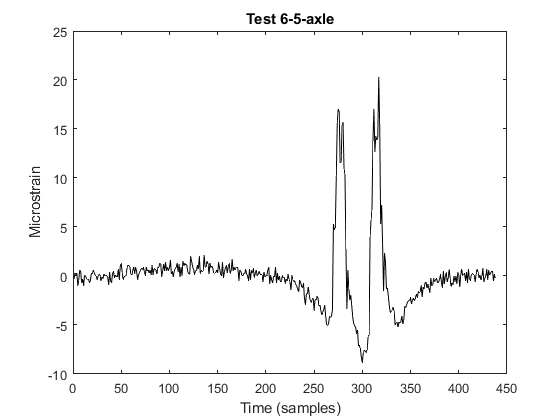

Test5_st40=Test5_st40+0.4*randn(length(Test5_st40),1);
plot(Test5_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

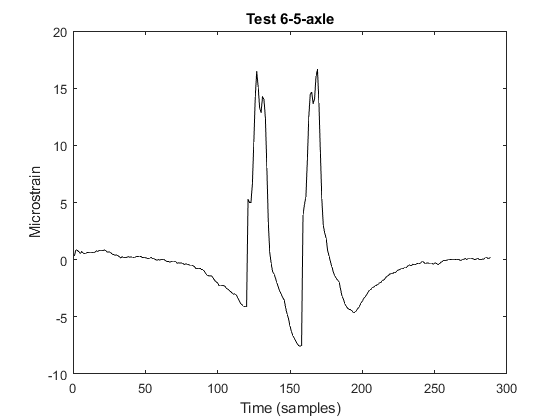


Test5_st40=Test5_st40';

T1=Test5_st40(150:269);
T2=Test5_st40(270:284);
T3=Test5_st40(285:307);
T4=Test5_st40(308:322);
T5=Test5_st40(323:end);


T1 = movmean(T1,[10 0]);

T2=movmean(T2,[2 0]);

T3 = movmean(T3,[10 0]);

T4=movmean(T4,[2 0]);

T5 = movmean(T5,[10 0]);


Test5_st40=[T1 T2 T3 T4 T5];

Test5_st40=Test5_st40';

plot(Test5_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

## Inputs

N_T5=4;          %% the number of axles
v1_T5=25;     %% m/s
f_T5=100;        %% Hz
d1_T5=0;         %% m
d2_T5=1.4;      %% m
d3_T5=8;      %% m
d4_T5=1.4;     %% m



Weights_T5=[9 9 9 9];

D1_vec_T5=[d1_T5 d1_T5+d2_T5 d1_T5+d2_T5+d3_T5 d1_T5+d2_T5+d3_T5+d4_T5];

c1_T5=D1_vec_T5(1)*f_T5/v1_T5;
c2_T5=D1_vec_T5(2)*f_T5/v1_T5;
c3_T5=D1_vec_T5(3)*f_T5/v1_T5;
c4_T5=D1_vec_T5(4)*f_T5/v1_T5;


C1_vec_T5=round([c1_T5 c2_T5 c3_T5 c4_T5]);

[row1_T5 col1_T5]=size(Test5_st40);
k1_T5=row1_T5;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T5]=A_MATRIX(N_T5,k1_T5,C1_vec_T5,Weights_T5);



## Test 6 (4-axle_LANE2)

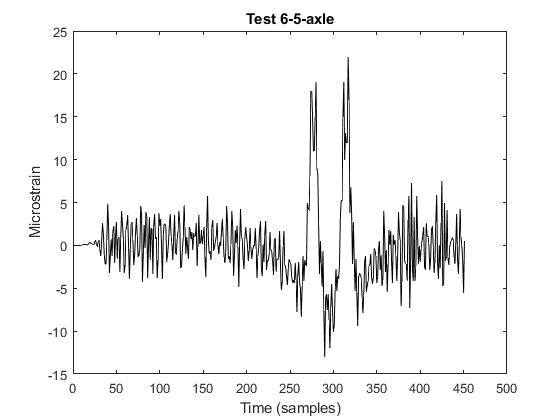

Data6 = textread('6035_Intact_Single4axle_TP3.txt');
plot(Data6,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

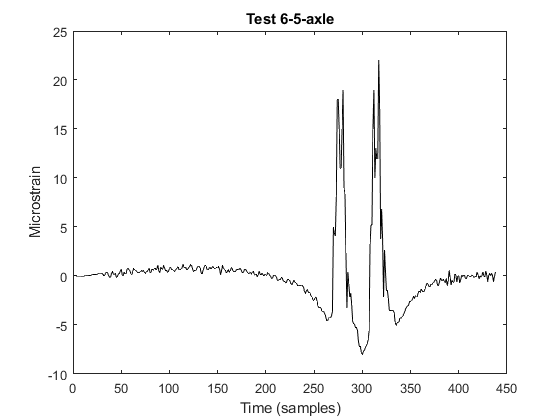

% 
Test6_st40=Data6;
Test6_st40=Test6_st40';

T1=Test6_st40(1:269);
T2=Test6_st40(270:284);
T3=Test6_st40(285:307);
T4=Test6_st40(308:322);
T5=Test6_st40(323:end-13);


T1 = movmean(T1,[10 0]);
T3 = movmean(T3,[10 0]);
T5 = movmean(T5,[10 0]);

Test6_st40=[T1 T2 T3 T4 T5];

Test6_st40=Test6_st40';

figure
plot(Test6_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

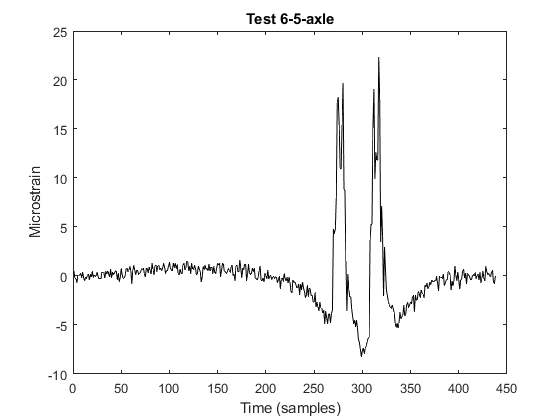

Test6_st40=Test6_st40+0.4*randn(length(Test6_st40),1);
plot(Test6_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

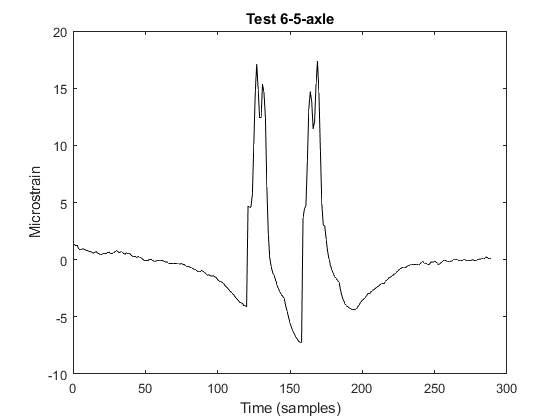



Test6_st40=Test6_st40';

T1=Test6_st40(150:269);
T2=Test6_st40(270:284);
T3=Test6_st40(285:307);
T4=Test6_st40(308:322);
T5=Test6_st40(323:end);

T1 = movmean(T1,[10 0]);

T2=movmean(T2,[2 0]);

T3 = movmean(T3,[10 0]);

T4=movmean(T4,[2 0]);

T5 = movmean(T5,[10 0]);


Test6_st40=[T1 T2 T3 T4 T5];

Test6_st40=Test6_st40';

plot(Test6_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

## Inputs

N_T6=4;          %% the number of axles
v1_T6=25;     %% m/s
f_T6=100;        %% Hz
d1_T6=0;         %% m
d2_T6=1.4;      %% m
d3_T6=8;      %% m
d4_T6=1.4;     %% m



Weights_T6=[9 9 9 9];

D1_vec_T6=[d1_T6 d1_T6+d2_T6 d1_T6+d2_T6+d3_T6 d1_T6+d2_T6+d3_T6+d4_T6];

c1_T6=D1_vec_T6(1)*f_T6/v1_T6;
c2_T6=D1_vec_T6(2)*f_T6/v1_T6;
c3_T6=D1_vec_T6(3)*f_T6/v1_T6;
c4_T6=D1_vec_T6(4)*f_T6/v1_T6;


C1_vec_T6=round([c1_T6 c2_T6 c3_T6 c4_T6]);

[row1_T6 col1_T6]=size(Test6_st40);
k1_T6=row1_T6;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T6]=A_MATRIX(N_T6,k1_T6,C1_vec_T6,Weights_T6);


## Test 7 (4-axle_LANE2)

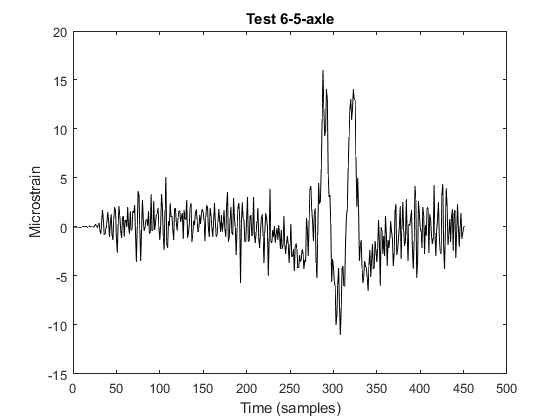

Data7 = textread('6035_Intact_Single5axle_TP1.txt');
plot(Data7,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

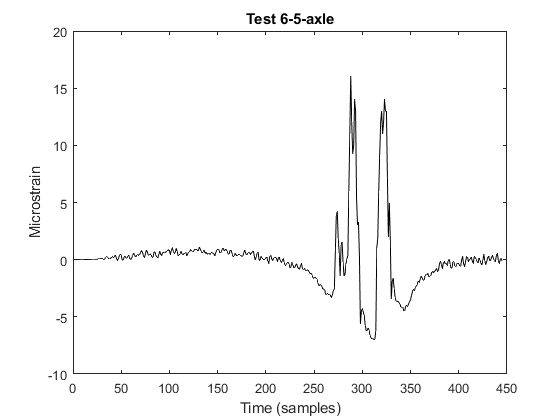

% 
Test7_st40=Data7;
Test7_st40=Test7_st40';

T1=Test7_st40(1:271);
T2=Test7_st40(272:277);
T3=Test7_st40(278:285);
T4=Test7_st40(286:297);
T5=Test7_st40(298:314);
T6=Test7_st40(315:330);
T7=Test7_st40(331:end-6);


T1 = movmean(T1,[10 0]);
T3 = movmean(T3,[10 0]);
T5 = movmean(T5,[10 0]);
T7 = movmean(T7,[10 0]);

Test7_st40=[T1 T2 T3 T4 T5 T6 T7];
Test7_st40=Test7_st40';

figure
plot(Test7_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

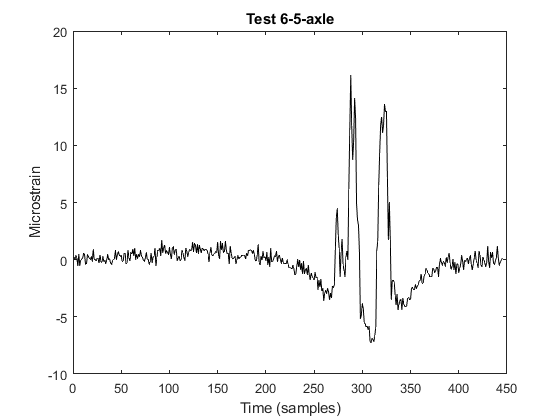

Test7_st40=Test7_st40+0.4*randn(length(Test7_st40),1);
plot(Test7_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

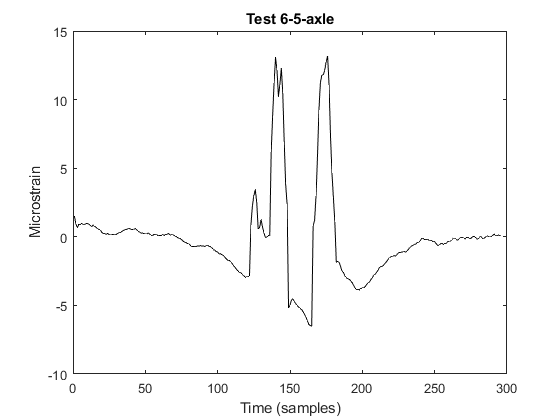



Test7_st40=Test7_st40';

T1=Test7_st40(150:271);
T2=Test7_st40(272:277);
T3=Test7_st40(278:285);
T4=Test7_st40(286:297);
T5=Test7_st40(298:314);
T6=Test7_st40(315:330);
T7=Test7_st40(331:end);

T1 = movmean(T1,[10 0]);

T2=movmean(T2,[2 0]);

T3 = movmean(T3,[10 0]);

T4=movmean(T4,[2 0]);

T5 = movmean(T5,[10 0]);

T6 = movmean(T6,[2 0]);
T7 = movmean(T7,[10 0]);

Test7_st40=[T1 T2 T3 T4 T5 T6 T7];

Test7_st40=Test7_st40';

plot(Test7_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

## Inputs

N_T7=5;          %% the number of axles
v1_T7=25;     %% m/s
f_T7=100;        %% Hz
d1_T7=0;         %% m
d2_T7=3.3528;      %% m
d3_T7=1.2192;      %% m
d4_T7=6.7056;     %% m
d5_T7=1.2192;      %% m


Weights_T7=[4.54 7.03 7.03 7.03 7.03];

D1_vec_T7=[d1_T7 d1_T7+d2_T7 d1_T7+d2_T7+d3_T7 d1_T7+d2_T7+d3_T7+d4_T7 d1_T7+d2_T7+d3_T7+d4_T7+d5_T7];

c1_T7=D1_vec_T7(1)*f_T7/v1_T7;
c2_T7=D1_vec_T7(2)*f_T7/v1_T7;
c3_T7=D1_vec_T7(3)*f_T7/v1_T7;
c4_T7=D1_vec_T7(4)*f_T7/v1_T7;
c5_T7=D1_vec_T7(5)*f_T7/v1_T7;

C1_vec_T7=round([c1_T7 c2_T7 c3_T7 c4_T7 c5_T7]);

[row1_T7 col1_T7]=size(Test7_st40);
k1_T7=row1_T7;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T7]=A_MATRIX(N_T7,k1_T7,C1_vec_T7,Weights_T7);

## Test 8 (4-axle_LANE2)

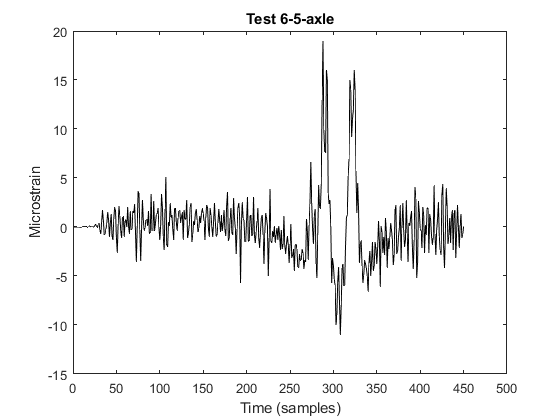

Data8 = textread('6035_Intact_Single5axle_TP2.txt');
plot(Data8,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

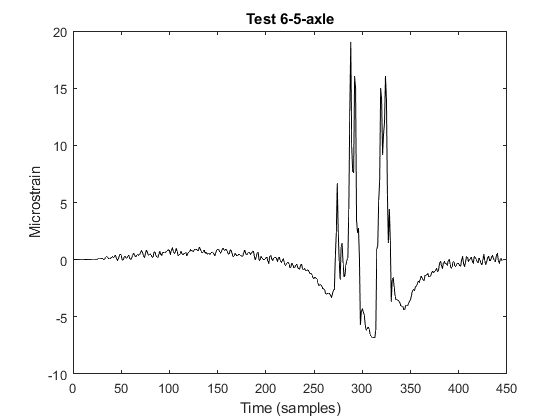

% 
Test8_st40=Data8;
Test8_st40=Test8_st40';

T1=Test8_st40(1:271);
T2=Test8_st40(272:277);
T3=Test8_st40(278:285);
T4=Test8_st40(286:297);
T5=Test8_st40(298:314);
T6=Test8_st40(315:330);
T7=Test8_st40(331:end-6);


T1 = movmean(T1,[10 0]);
T3 = movmean(T3,[10 0]);
T5 = movmean(T5,[10 0]);
T7 = movmean(T7,[10 0]);

Test8_st40=[T1 T2 T3 T4 T5 T6 T7];
Test8_st40=Test8_st40';

figure
plot(Test8_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

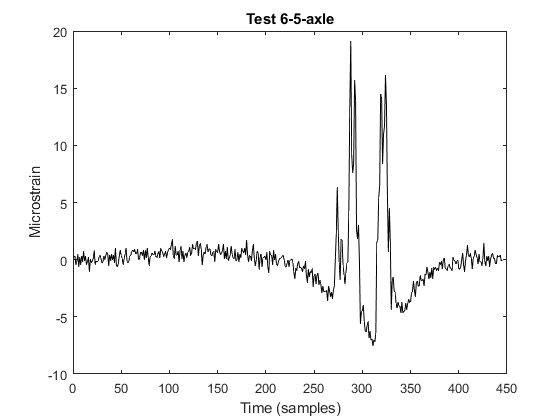

Test8_st40=Test8_st40+0.4*randn(length(Test8_st40),1);
plot(Test8_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

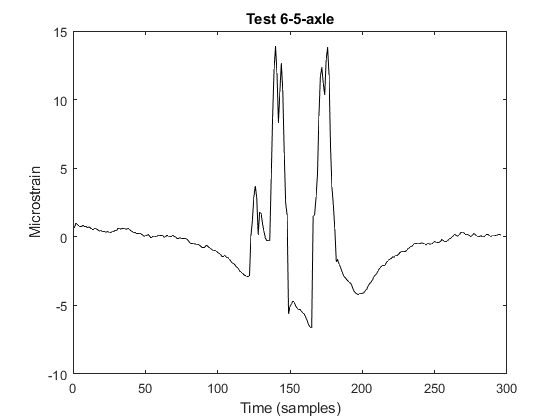



Test8_st40=Test8_st40';

T1=Test8_st40(150:271);
T2=Test8_st40(272:277);
T3=Test8_st40(278:285);
T4=Test8_st40(286:297);
T5=Test8_st40(298:314);
T6=Test8_st40(315:330);
T7=Test8_st40(331:end);


T1 = movmean(T1,[10 0]);

T2=movmean(T2,[2 0]);

T3 = movmean(T3,[10 0]);

T4=movmean(T4,[2 0]);

T5 = movmean(T5,[10 0]);

T6 = movmean(T6,[2 0]);

T7 = movmean(T7,[10 0]);


Test8_st40=[T1 T2 T3 T4 T5 T6 T7];

Test8_st40=Test8_st40';

plot(Test8_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

## Inputs

N_T8=5;          %% the number of axles
v1_T8=25;     %% m/s
f_T8=100;        %% Hz
d1_T8=0;         %% m
d2_T8=3.3528;      %% m
d3_T8=1.2192;      %% m
d4_T8=6.7056;     %% m
d5_T8=1.2192;      %% m


Weights_T8=[4.54 7.03 7.03 7.03 7.03];

D1_vec_T8=[d1_T8 d1_T8+d2_T8 d1_T8+d2_T8+d3_T8 d1_T8+d2_T8+d3_T8+d4_T8 d1_T8+d2_T8+d3_T8+d4_T8+d5_T8];

c1_T8=D1_vec_T8(1)*f_T8/v1_T8;
c2_T8=D1_vec_T8(2)*f_T8/v1_T8;
c3_T8=D1_vec_T8(3)*f_T8/v1_T8;
c4_T8=D1_vec_T8(4)*f_T8/v1_T8;
c5_T8=D1_vec_T8(5)*f_T8/v1_T8;

C1_vec_T8=round([c1_T8 c2_T8 c3_T8 c4_T8 c5_T8]);

[row1_T8 col1_T8]=size(Test8_st40);
k1_T8=row1_T8;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T8]=A_MATRIX(N_T8,k1_T8,C1_vec_T8,Weights_T8);


## Test 9 (4-axle_LANE2)

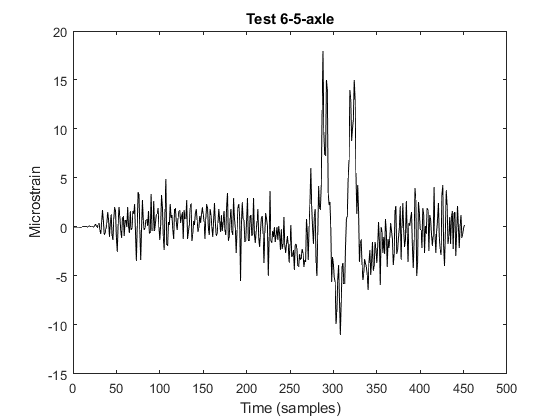

Data9 = textread('6035_Intact_Single5axle_TP3.txt');
plot(Data9,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

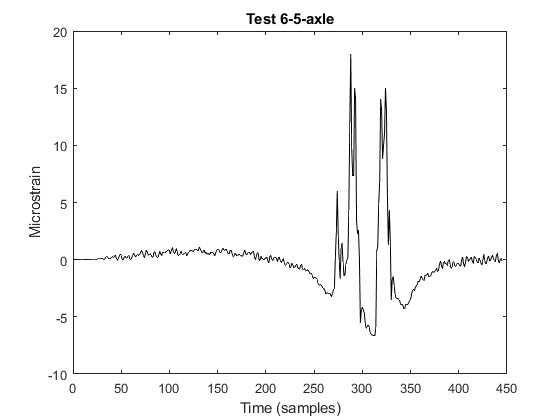

% 
Test9_st40=Data9;
Test9_st40=Test9_st40';

T1=Test9_st40(1:271);
T2=Test9_st40(272:277);
T3=Test9_st40(278:285);
T4=Test9_st40(286:297);
T5=Test9_st40(298:314);
T6=Test9_st40(315:330);
T7=Test9_st40(331:end-6);


T1 = movmean(T1,[10 0]);
T3 = movmean(T3,[10 0]);
T5 = movmean(T5,[10 0]);
T7 = movmean(T7,[10 0]);

Test9_st40=[T1 T2 T3 T4 T5 T6 T7];
Test9_st40=Test9_st40';

figure
plot(Test9_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

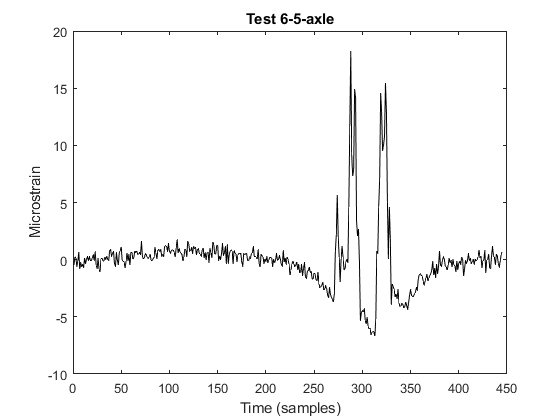

Test9_st40=Test9_st40+0.4*randn(length(Test9_st40),1);
plot(Test9_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

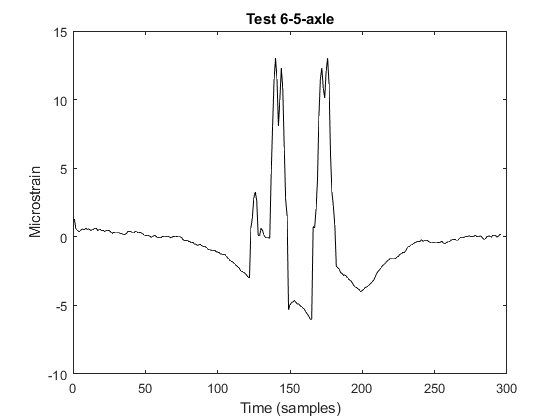



Test9_st40=Test9_st40';

T1=Test9_st40(150:271);
T2=Test9_st40(272:277);
T3=Test9_st40(278:285);
T4=Test9_st40(286:297);
T5=Test9_st40(298:314);
T6=Test9_st40(315:330);
T7=Test9_st40(331:end);



T1 = movmean(T1,[10 0]);

T2=movmean(T2,[2 0]);

T3 = movmean(T3,[10 0]);

T4=movmean(T4,[2 0]);

T5 = movmean(T5,[10 0]);

T6=movmean(T6,[2 0]);

T7 = movmean(T7,[10 0]);


Test9_st40=[T1 T2 T3 T4 T5 T6 T7];

Test9_st40=Test9_st40';

plot(Test9_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

## Inputs

N_T9=5;          %% the number of axles
v1_T9=25;     %% m/s
f_T9=100;        %% Hz
d1_T9=0;         %% m
d2_T9=3.3528;      %% m
d3_T9=1.2192;      %% m
d4_T9=6.7056;     %% m
d5_T9=1.2192;      %% m


Weights_T9=[4.54 7.03 7.03 7.03 7.03];

D1_vec_T9=[d1_T9 d1_T9+d2_T9 d1_T9+d2_T9+d3_T9 d1_T9+d2_T9+d3_T9+d4_T9 d1_T9+d2_T9+d3_T9+d4_T9+d5_T9];

c1_T9=D1_vec_T9(1)*f_T9/v1_T9;
c2_T9=D1_vec_T9(2)*f_T9/v1_T9;
c3_T9=D1_vec_T9(3)*f_T9/v1_T9;
c4_T9=D1_vec_T9(4)*f_T9/v1_T9;
c5_T9=D1_vec_T9(5)*f_T9/v1_T9;

C1_vec_T9=round([c1_T9 c2_T9 c3_T9 c4_T9 c5_T9]);

[row1_T9 col1_T9]=size(Test9_st40);
k1_T9=row1_T9;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T9]=A_MATRIX(N_T9,k1_T9,C1_vec_T9,Weights_T9);


The tests 1-9 were all for RefIL calculation. These ILs are computed as follows and named IL17,18,19 for 3-axle, 4-axle, and 5-axle trucks. Also, for each individual test (1-9) we calculate the ILs and then compure it with the RefILs. These ILs are named Inf_Line1 through Inf_Line9. According to my dissertation and the methodology for threshold calculation, we compute the SSE of the new ILs (Inf_Line1 through Inf_Line9) and RefILs. For each, we repeat the run three times to include three noise contents for each TP.

## Influence Line 


Inf_Line1=inv(A_mat_T1'*A_mat_T1)*A_mat_T1'*Test1_st40; %% IL1 for test 1
Inf_Line2=inv(A_mat_T2'*A_mat_T2)*A_mat_T2'*Test2_st40; %% IL2 for test 2
Inf_Line3=inv(A_mat_T3'*A_mat_T3)*A_mat_T3'*Test3_st40; %% IL3 for test 3
Inf_Line4=inv(A_mat_T4'*A_mat_T4)*A_mat_T4'*Test4_st40; %% IL4 for test 4
Inf_Line5=inv(A_mat_T5'*A_mat_T5)*A_mat_T5'*Test5_st40; %% IL5 for test 5
Inf_Line6=inv(A_mat_T6'*A_mat_T6)*A_mat_T6'*Test6_st40; %% IL6 for test 6
Inf_Line7=inv(A_mat_T7'*A_mat_T7)*A_mat_T7'*Test7_st40; %% IL7 for test 7
Inf_Line8=inv(A_mat_T8'*A_mat_T8)*A_mat_T8'*Test8_st40; %% IL8 for test 8
Inf_Line9=inv(A_mat_T9'*A_mat_T9)*A_mat_T9'*Test9_st40; %% IL9 for test 9

% %% 3axle (RefIL)
Inf_Line17=inv(A_mat_T1'*A_mat_T1+A_mat_T2'*A_mat_T2+A_mat_T3'*A_mat_T3)*(A_mat_T1'*Test1_st40+A_mat_T2'*Test2_st40+A_mat_T3'*Test3_st40);

% %% 4axle (RefIL)
Inf_Line18=inv(A_mat_T4'*A_mat_T4+A_mat_T5'*A_mat_T5+A_mat_T6'*A_mat_T6)*(A_mat_T4'*Test4_st40+A_mat_T5'*Test5_st40+A_mat_T6'*Test6_st40);

% %% 5axle (RefIL)
Inf_Line19=inv(A_mat_T7'*A_mat_T7+A_mat_T8'*A_mat_T8+A_mat_T9'*A_mat_T9)*(A_mat_T7'*Test7_st40+A_mat_T8'*Test8_st40+A_mat_T9'*Test9_st40);


% %%% Not that necessary, but here, I am just smoothing the unnecessary parts of the ILs.

Inf_Line1=Inf_Line1';
Inf_Line1=[(movmean(Inf_Line1(1:118),[20 0])) Inf_Line1(119:135) movmean(Inf_Line1(136:end),[0 20])];


Inf_Line2=Inf_Line2';
Inf_Line2=[(movmean(Inf_Line2(1:118),[20 0])) Inf_Line2(119:135) movmean(Inf_Line2(136:end),[0 20])];

Inf_Line3=Inf_Line3';
Inf_Line3=[(movmean(Inf_Line3(1:118),[20 0])) Inf_Line3(119:135) movmean(Inf_Line3(136:end),[0 20])];


Inf_Line4=Inf_Line4';
Inf_Line4=[(movmean(Inf_Line4(1:118),[20 0])) Inf_Line4(119:135) movmean(Inf_Line4(136:end),[0 20])];


Inf_Line5=Inf_Line5';
Inf_Line5=[(movmean(Inf_Line5(1:118),[20 0])) Inf_Line5(119:135) movmean(Inf_Line5(136:end),[0 20])];


Inf_Line6=Inf_Line6';
Inf_Line6=[(movmean(Inf_Line6(1:118),[20 0])) Inf_Line6(119:135) movmean(Inf_Line6(136:end),[0 20])];


Inf_Line7=Inf_Line7';
Inf_Line7=[(movmean(Inf_Line7(1:118),[20 0])) Inf_Line7(119:135) movmean(Inf_Line7(136:end),[0 20])];


Inf_Line8=Inf_Line8';
Inf_Line8=[(movmean(Inf_Line8(1:118),[20 0])) Inf_Line8(119:135) movmean(Inf_Line8(136:end),[0 20])];

Inf_Line9=Inf_Line9';
Inf_Line9=[(movmean(Inf_Line9(1:118),[20 0])) Inf_Line9(119:135) movmean(Inf_Line9(136:end),[0 20])];
% 
Inf_Line17=Inf_Line17';
Inf_Line17=[(movmean(Inf_Line17(1:118),[20 0])) Inf_Line17(119:135) movmean(Inf_Line17(136:end),[0 20])];

Inf_Line18=Inf_Line18';
Inf_Line18=[(movmean(Inf_Line18(1:118),[20 0])) Inf_Line18(119:135) movmean(Inf_Line18(136:end),[0 20])];

Inf_Line19=Inf_Line19';
Inf_Line19=[(movmean(Inf_Line19(1:118),[20 0])) Inf_Line19(119:135) movmean(Inf_Line19(136:end),[0 20])];

Here, we now plot the Test ILs vs. RefIL

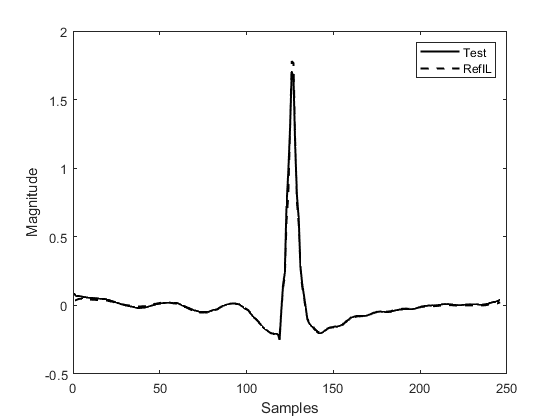

figure
plot(Inf_Line1,'-k' ,'Linewidth', 1.5)
hold on
plot(Inf_Line17,'--k' , 'Linewidth', 1.5)
legend('Test','RefIL')

xlabel('Samples')
ylabel('Magnitude')

Here, we compute the Damage Indicator (DI) for each test and the RefIL. Per the instruction in my dissertation (chapter 4), we need to repeat the process three times for each case and write down the DI values somewhere and later perform a 95% confidence analysis on the DI values for each truck (nine DIs for each) and to take the upper limit of the confidence interval that is our threshold for that particular truck.

BB=0;
for i=1:length(Inf_Line1)
PPP=[Inf_Line1(i)-Inf_Line17(i)]^2;
BB=BB+PPP;
end

DLocator=BB

DLocator = 0.0756